# Core Tasks

## Task 1- Load and plot the MRI volumes and masks

loadData

### Visualise slice of 1st healthy and pre-eclampsia sample

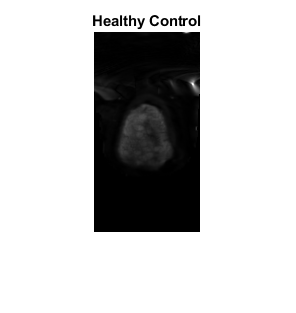

slice_of_interest = 7;
imshow(flipud(squeeze(V_healthy(:,:,slice_of_interest,1))), []);
title("Healthy Control");

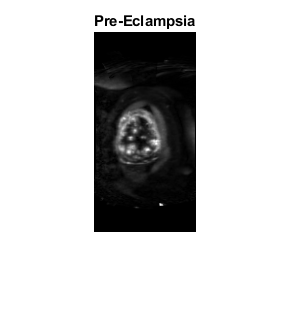

imshow(flipud(squeeze(V_pre_eclampsia(:,:,slice_of_interest,1))), []);
title("Pre-Eclampsia");

## Visualise placenta and uterine wall masks

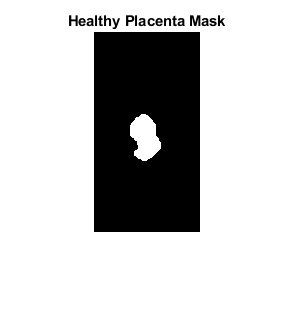

imshow(flipud(squeeze(M_healthy_placenta(:,:,slice_of_interest))), []);
title("Healthy Placenta Mask");

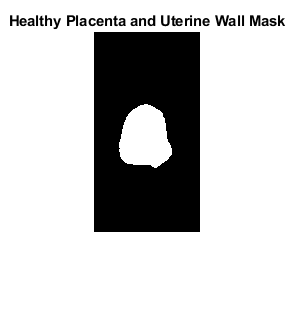

imshow(flipud(squeeze(M_healthy_placenta_uterine_wall(:,:,slice_of_interest))), []); % larger
title("Healthy Placenta and Uterine Wall Mask");

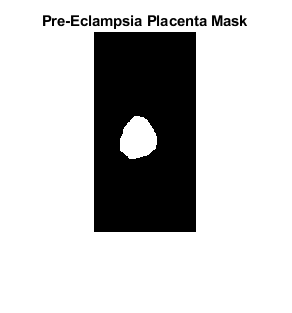

imshow(flipud(squeeze(M_pre_eclampsia_placenta(:,:,slice_of_interest))), []);
title("Pre-Eclampsia Placenta Mask");

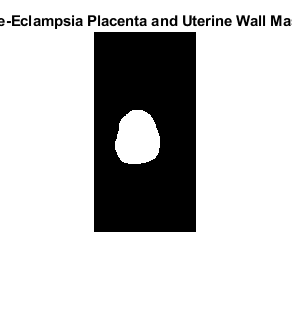

figure(4);
imshow(flipud(squeeze(M_pre_eclampsia_placenta_uterine_wall(:,:,slice_of_interest))), []);
title("Pre-Eclampsia Placenta and Uterine Wall Mask");

## Load and plot the MRI acquisition parameters

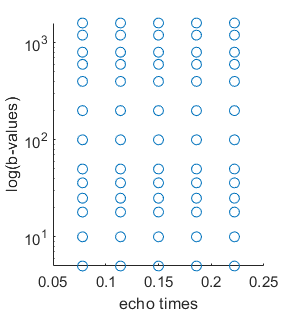

unique_b_values_number = numel(unique(grad_echo(:,4)));
unique_echo_times_number = numel(unique(grad_echo(:,5)));

% 2D scatter plot
x = grad_echo(:,5);
y = grad_echo(:,4);
scatter(x,y);
set(gca, 'YScale', 'log')
xlabel("echo times");
ylabel("log(b-values)");